# --- 1. Setup: Load an image and add Gaussian noise ---

Read a sample image and convert to grayscale double format

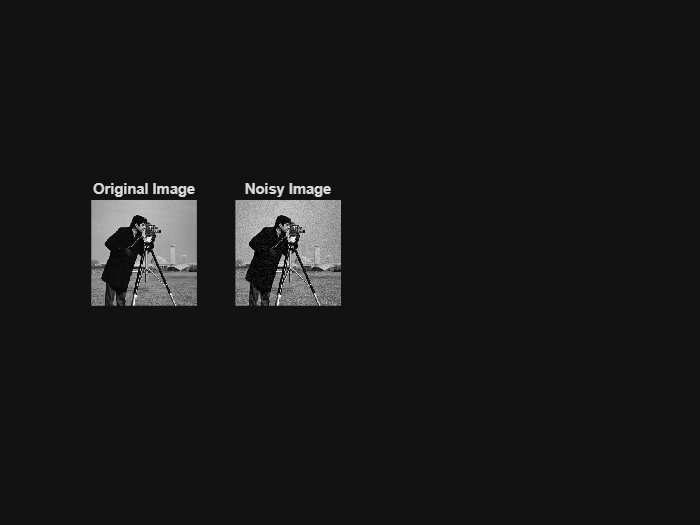

originalImage = im2double(imread('cameraman.tif'));
% Define the noise standard deviation
noiseSigma = 0.04;
% Add Gaussian noise to the image
noisyImage = imnoise(originalImage, 'gaussian', 0, noiseSigma^2);
% Display the original and noisy images
figure('Name', 'Gaussian Noise Denoising Comparison');
subplot(1, 4, 1); imshow(originalImage); title('Original Image');
subplot(1, 4, 2); imshow(noisyImage); title('Noisy Image');

## --- 2. Traditional Filter (Adaptive Wiener Filter) ---

The Wiener filter is a traditional adaptive filter that performs well with additive white Gaussian noise. It adapts its smoothing level based on local variance, preserving edges better than a simple Gaussian blur. We provide the estimated noise variance for better results.

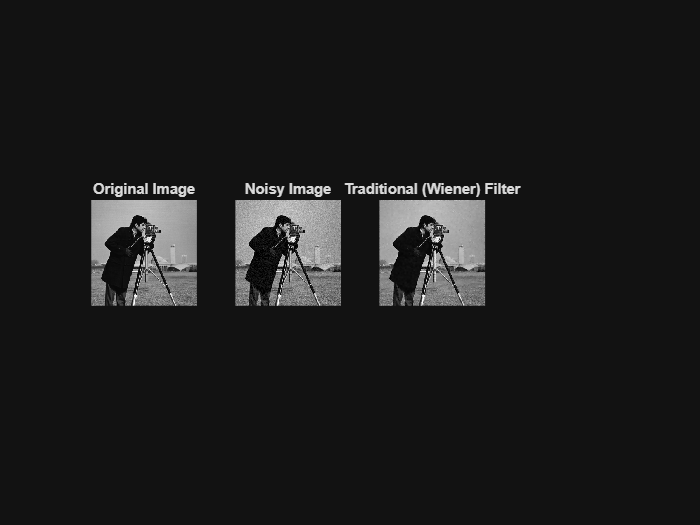

traditionalFiltered = wiener2(noisyImage, [5 5], noiseSigma^2);
% Display the result of the traditional filter
subplot(1, 4, 3); imshow(traditionalFiltered); title('Traditional (Wiener) Filter');

## --- 3. AI Filter (Pre-trained DnCNN) ---

The pre-trained DnCNN network in MATLAB is specifically designed for grayscale images with Gaussian noise within a certain range. It automatically learns complex features to remove noise while preserving details. Load the pre-trained denoising CNN model

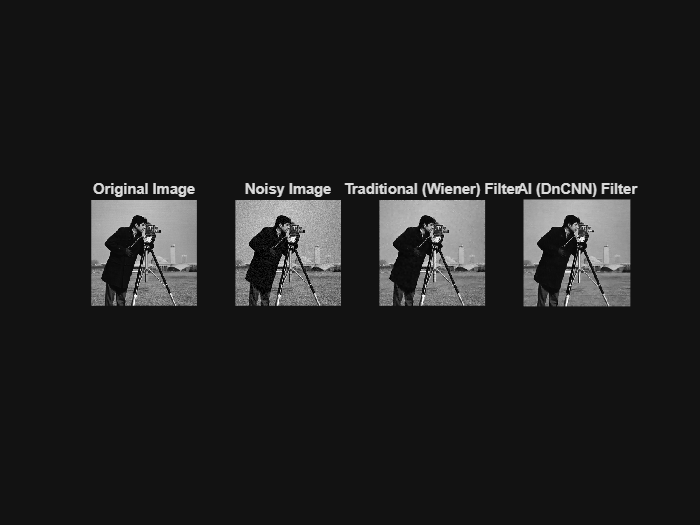

net = denoisingNetwork('DnCNN');
% Apply the deep learning filter
aiFiltered = denoiseImage(noisyImage, net);
% Display the result of the AI filter
subplot(1, 4, 4); imshow(aiFiltered); title('AI (DnCNN) Filter');

## --- 4. Quantitative Evaluation (PSNR and SSIM) ---

Calculate PSNR (Peak Signal-to-Noise Ratio) and SSIM (Structural Similarity Index) Higher values indicate better quality.

psnrNoisy = psnr(noisyImage, originalImage);
ssimNoisy = ssim(noisyImage, originalImage);
psnrTraditional = psnr(traditionalFiltered, originalImage);
ssimTraditional = ssim(traditionalFiltered, originalImage);
psnrAI = psnr(aiFiltered, originalImage);
ssimAI = ssim(aiFiltered, originalImage);
% Display the metrics
fprintf('\n--- Image Quality Metrics Comparison ---\n');


--- Image Quality Metrics Comparison ---


fprintf('Method | PSNR (dB) | SSIM\n');

Method | PSNR (dB) | SSIM


fprintf('----------------------|-----------|----------\n');

----------------------|-----------|----------


fprintf('Noisy Image | %8.4f | %8.4f\n', psnrNoisy, ssimNoisy);

Noisy Image |  28.1151 |   0.6308


fprintf('Traditional (Wiener) | %8.4f | %8.4f\n', psnrTraditional, ssimTraditional);

Traditional (Wiener) |  32.0862 |   0.8824


fprintf('AI (DnCNN) | %8.4f | %8.4f\n', psnrAI, ssimAI);

AI (DnCNN) |  32.5396 |   0.8968


## --- 5. Visual Observation ---

The output will show that the Wiener filter does a good job of smoothing, but the AI-based DnCNN filter typically yields higher PSNR and SSIM values and better visual results by preserving fine details and texture more effectively than traditional methods.